# Q-Learning Standing Balance — Policy Evaluation Live Script

**Writer: Amin Nasr — SMPLab —** [**amin.nasr@ubc.ca**](mailto:amin.nasr@ubc.ca)

This live script loads a pre-trained Q-value policy map and runs a single test simulation of the AP inverted pendulum standing balance model. No learning is performed here — the agent acts greedily from the loaded policy.

## 1. Initialise Workspace

clear
clc
close all

## 2. Simulation & Timing Parameters

Define the time step, total duration, and sensorimotor delay.

dtms           = 4;           % Time step (ms)
dt             = dtms / 1000; % Time step (s)
T              = 60;          % Simulation duration (s)
GainTorque     = 1;           % Torque gain (keep at 1)

timing_delay     = 52;        % Total sensorimotor delay (ms)
decisionLoop     = timing_delay / dtms;   % Decision every N time steps
delaybuffAction  = timing_delay / dtms;
delaybuffSensory = timing_delay / dtms;

fprintf('Simulation: %.0f s  |  dt = %d ms  |  Delay = %d ms\n', T, dtms, timing_delay)

## 3. State & Action Space

Discretisation of angle (theta), angular velocity (theta-dot), and torque actions.

ThRange    = [-3,  6];    % Angle range (deg)
ThDotRange = [-20, 20];   % Angular velocity range (deg/s)
thetaNState  = 10;
thetaDNState = 11;

fprintf('Theta range: [%d, %d] deg  |  ThetaDot range: [%d, %d] deg/s\n', ...
    ThRange(1), ThRange(2), ThDotRange(1), ThDotRange(2))

## 4. Instantiate Environment

The Environment class handles pendulum dynamics, noise, muscle dynamics, and passive ankle stiffness (Loram et al. 2007).

env = Environment;
env.setMyConstant(1, ThRange, ThDotRange);
n = env.num_samples;   % Total number of time steps

% Noise & metabolic cost coefficients
env.mn_coeff     = 1;
env.thn_coeff    = 0.002;
env.thdotn_coeff = 0.0036;

fprintf('Pendulum: m=%.0f kg, h=%.2f m, I=%.2f kg.m^2\n', env.m, env.h, env.I)

## 5. Instantiate Q-Agent

The QAgent class holds the Q-value table and the action/policy selection logic. Metabolic cost coefficients MC and MCC are set here.

qagent = QAgent;
qagent.setMyConstant(1, ThRange, ThDotRange, thetaNState, thetaDNState, ...
    [1 1], [-200 -200], 0.975, 75, 7);

% Metabolic cost weights
qagent.cst  = 0.01;   % MC  — cost proportional to torque magnitude
qagent.cstc = 0.05;   % MCC — cost proportional to torque change

fprintf('Agent: %d theta states × %d thetadot states × %d actions\n', ...
    qagent.n_theta, qagent.n_thetadot, qagent.n_action)
fprintf('MC = %.4f,  MCC = %.4f\n', qagent.cst, qagent.cstc)

## 6. Load Pre-Trained Policy Map

Load the saved Q-value table from a previous training run. The file should contain the variable `Q_vals` (size: n_states × n_actions). Place the .mat file in the same directory as this script.

policyFile = 'PolicyMap.mat';   % <-- update filename if needed
loaded = load(policyFile);

% Accept either Q_vals directly or the actMap struct depending on save format
if isfield(loaded, 'Q_vals')
    qagent.Q_vals = loaded.Q_vals;
    disp('Q_vals loaded successfully from PolicyMap.mat')
elseif isfield(loaded, 'actMap')
    % If only actMap was saved, we cannot restore full Q_vals.
    % We will use the actMap directly in the policy step below.
    actMap_loaded = loaded.actMap;
    disp('actMap loaded (Q_vals not available — using actMap directly)')
else
    error('Policy file must contain Q_vals or actMap.')
end

## 7. Run One Test Simulation

The agent selects actions greedily (no exploration). The pendulum starts upright at zero angle and zero velocity.


now_state   = [0; 0] * pi/180;    % [thetadot; theta] — both zero
true_state  = now_state;
now_act     = qagent.action_zero;

[delayed_disc_th, delayed_disc_thdot] = qagent.find_state(now_state);

% Initialise delay buffers
action_buff = ones(delaybuffAction,  1) * floor(qagent.n_action / 2);
state_buff  = repmat(now_state, 1, delaybuffSensory);

% Initialise history storage: rows = [thetadot, theta, perceived_thdot, perceived_th, c_torque, exerted_torque]
state_history = zeros(6, n);
failure_flag  = 0;
result_char   = 's';
c_torque      = 0;
true_torque   = 0;

env.reset_pt(true_state);

disp('Running test simulation...')

Running test simulation...



for iTime = 1:n

    % --- Delay buffers ---
    action_buff(delaybuffAction) = now_act;
    delayed_act  = action_buff(1);
    action_buff(1) = [];

    state_buff(:, delaybuffSensory) = now_state;
    delayed_state = state_buff(:, 1);
    state_buff(:, 1) = [];

    % --- Decision step (every decisionLoop time steps) ---
    if mod(iTime, decisionLoop) == 1

        act_prev        = now_act;
        disc_prev       = delayed_disc_th;
        disc_prevdot    = delayed_disc_thdot;

        [delayed_disc_th, delayed_disc_thdot] = qagent.find_state(delayed_state);
        if isempty(delayed_disc_thdot)
            delayed_disc_thdot = thetaDNState;
        end
        delayed_q_ind = qagent.qind(delayed_disc_thdot, delayed_disc_th);

        % Greedy policy — no exploration
        % now_act  = qagent.policy(delayed_q_ind);
        % c_torque = qagent.n_acts(delayed_act) * GainTorque;

        now_act = actMap_loaded(delayed_disc_thdot, delayed_disc_th);
        c_torque = now_act;

    end

    % --- Muscle dynamics ---
    if sign(c_torque) == -1
        MVC = 256 * GainTorque;
    else
        MVC = 84  * GainTorque;
    end
    true_torque = env.muscle_dyn(c_torque, MVC, dt);

    % --- Passive ankle stiffness ---
    ps_torque = env.passive_torque(true_state);

    % --- System dynamics ---
    [now_state, true_state, exerted_torque] = env.dynamics_test( ...
        true_state, true_torque, ps_torque, iTime, 1, dt);

    % --- Store history ---
    state_history(1:2, iTime) = true_state;
    state_history(3:4, iTime) = now_state;
    state_history(5,   iTime) = c_torque;
    state_history(6,   iTime) = exerted_torque;

    % --- Failure check ---
    failure_flag = env.failure_check(delayed_state);
    if failure_flag == 1
        result_char = 'f';
        fprintf('Simulation failed at t = %.2f s\n', iTime * dt)
        break
    end

end

if failure_flag == 0
    fprintf('Simulation completed successfully (%.0f s)\n', T)
end

Simulation completed successfully (60 s)


## 8. Plot — Pendulum Angle Over Time

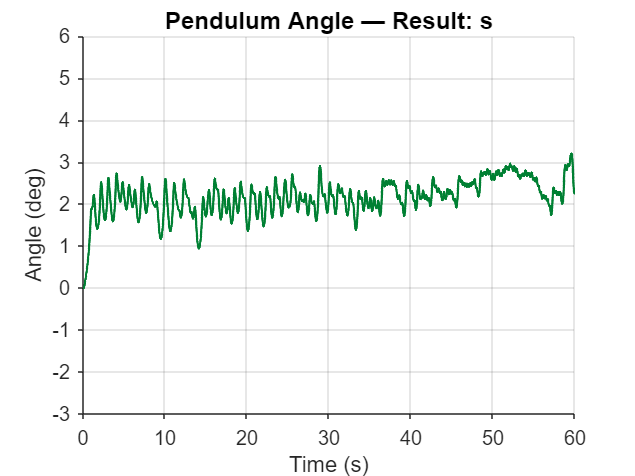

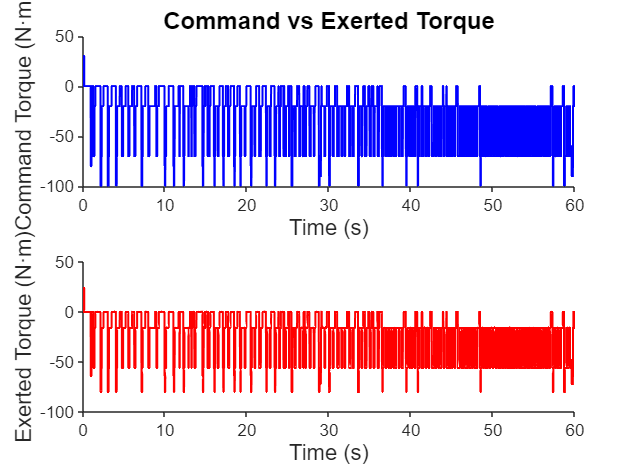

t_axis = dt:dt:iTime*dt;

figure;
plot(t_axis, state_history(2, 1:iTime)*180/pi, 'Color', [0 0.5 0.2], 'LineWidth', 1.2)
xlabel('Time (s)', 'FontSize', 11)
ylabel('Angle (deg)', 'FontSize', 11)
title(['Pendulum Angle — Result: ', result_char], 'FontSize', 12)
ylim(env.th_range)
xlim([0 T])
grid on
set(gca, 'TickDir', 'out', 'Box', 'off')

## 10. Plot — Policy Map

Visualise the greedy policy as a colour map over the state space. Each cell shows the torque the agent would command from that state.

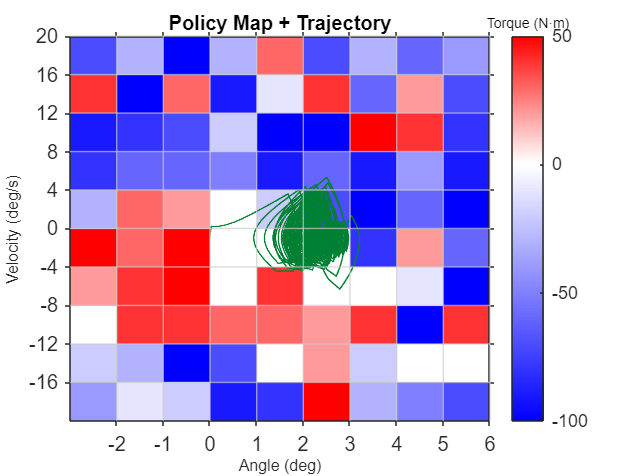

actMap = actMap_loaded;

% Axis values
x = (2:thetaNState)  - 1 + min(ThRange);
y = (2:thetaDNState) - 1;
y = y * 4 + min(ThDotRange);

xShift = (ThRange(2)    - ThRange(1))    / (2*(thetaNState  - 1));
yShift = (ThDotRange(2) - ThDotRange(1)) / (2*(thetaDNState - 1));

% Custom blue–white–red colormap centred at zero torque
dataMin = -100;  dataMax = 50;
zeroPoint    = (0 - dataMin) / (dataMax - dataMin);
cmapSize     = 256;
midPoint     = round(cmapSize * zeroPoint);
blueToWhite  = [linspace(0,1,midPoint)',   linspace(0,1,midPoint)',   ones(midPoint,1)];
whiteToRed   = [ones(cmapSize-midPoint,1), linspace(1,0,cmapSize-midPoint)', linspace(1,0,cmapSize-midPoint)'];
customCmap   = [blueToWhite; whiteToRed];

figure;
imagesc(x, y, actMap(2:end, 2:end)'); axis xy;
xticks(x + xShift);  xticklabels(arrayfun(@num2str, x, 'UniformOutput', false));
yticks(y + yShift);  yticklabels(arrayfun(@num2str, y, 'UniformOutput', false));
colormap(customCmap); caxis([dataMin dataMax]);
hcb = colorbar; title(hcb, 'Torque (N·m)', 'FontSize', 7)
hold on
% Grid lines
for col = x(1)+(x(2)-x(1))/2 : x(2)-x(1) : x(end)+(x(2)-x(1))/2
    xline(col, 'Color', [0.8 0.8 0.8], 'LineWidth', 0.7);
end
for row = y(1)+(y(2)-y(1))/2 : y(2)-y(1) : y(end)+(y(2)-y(1))/2
    yline(row, 'Color', [0.8 0.8 0.8], 'LineWidth', 0.7);
end
% Overlay trajectory
plot(state_history(2, 1:iTime)*180/pi + 0.5, ...
     state_history(1, 1:iTime)*180/pi + 1, ...
     'LineWidth', 0.75, 'Color', [0 0.5 0.2 0.5])
hold off
title('Policy Map + Trajectory', 'FontSize', 10)
xlabel('Angle (deg)', 'FontSize', 8)
ylabel('Velocity (deg/s)', 'FontSize', 8)
set(gca, 'TickDir', 'out')